clear all
[data,numChan,labels,txt,fs,gain,prefiltering,ChanDim] = eeg_read_bdf("C:\Users\Peter\Desktop\CGX\data\석동열\ex_1.bdf",'all','n');

data1 = data;
data1(1:19,:) = bandpass(1e-6*data1(1:19,:)',[0.5 100], 500)'; 

d = designfilt('bandstopiir','FilterOrder',2, ...
               'HalfPowerFrequency1',59,'HalfPowerFrequency2',61, ...
               'DesignMethod','butter','SampleRate',500);
buttLoop(1:19,:) = filtfilt(d,data1(1:19,:));

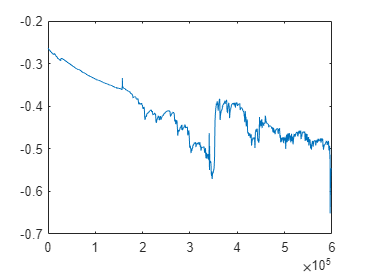

plot(data(1,:)*1e-6)

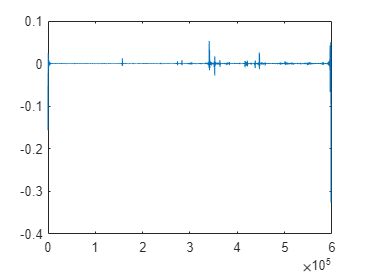

plot(data1(1,:))

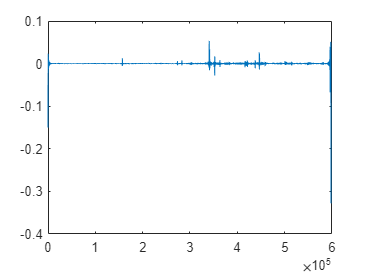

plot(buttLoop(1,:))

clear data
[data,numChan,labels,txt,fs,gain,prefiltering,ChanDim] = eeg_read_bdf("C:\Users\Peter\Desktop\CGX\data\석동열\ex_2.bdf",'all','n');

data2 = data;
data2(1:19,:) = bandpass(data2(1:19,:)',[0.5 100], 500)';
clear data

Run_start = find(data1(27,:) == 3);
Class_1 = find(data1(27,:) == 1);
Class_2 = find(data1(27,:) == 2);

% aug = 10:10:250;
aug = 0;

for j = length(Class_1):-1:1
    Class_1 = [Class_1 aug+Class_1(j)];
end

for j = length(Class_2):-1:1
    Class_2 = [Class_2 Class_2(j)+aug];
end

cue_offset = 625; % 1.25sec * 500Hz
imagery_duration  = floor(2.75*500); % 3sec * 500Hz
rear_offset = cue_offset + imagery_duration;

% channel_selection = [5 7 8 13 14 15 18 19];
channel_selection = 1:19;
m = 32

for i = 1:length(Class_1)
    b_group_1 = data1(channel_selection,Class_1(i)+cue_offset:Class_1(i)+rear_offset);
    group_1(i,:,:) = b_group_1;
    [K1(i,:,:), A1(i,:,:)] = my_SAX(b_group_1',m);
    
    Y1(i,1) = 1;
end

for i = 1:length(Class_2)
    b_group_2 = data1(channel_selection,Class_2(i)+cue_offset:Class_2(i)+rear_offset);
    group_2(i,:,:) = b_group_2;
    [K2(i,:,:), A2(i,:,:)] = my_SAX(b_group_2',m);
    Y2(i,1) = 2;
end

clear Class_1 Class_2
Run_start = find(data2(27,:) == 3);
Class_1 = find(data2(27,:) == 1);
Class_2 = find(data2(27,:) == 2);

% aug = 10:10:250;
aug = 0;

for j = length(Class_1):-1:1
    Class_1 = [Class_1 aug+Class_1(j)];
end

for j = length(Class_2):-1:1
    Class_2 = [Class_2 Class_2(j)+aug];
end

cue_offset = 625; % 1.25sec * 500Hz
imagery_duration  = floor(2.75*500); % 3sec * 500Hz
rear_offset = cue_offset + imagery_duration;

% channel_selection = [5 7 8 13 14 15 18 19];
channel_selection = 1:19;
m = 32

for i = 1:length(Class_1)
    b_group_1 = data2(channel_selection,Class_1(i)+cue_offset:Class_1(i)+rear_offset);
    groupp_1(i,:,:) = b_group_1;
    [KK1(i,:,:), AA1(i,:,:)] = my_SAX(b_group_1',m);
    
    YY1(i,1) = 1;
end

for i = 1:length(Class_2)
    b_group_2 = data2(channel_selection,Class_2(i)+cue_offset:Class_2(i)+rear_offset);
    groupp_2(i,:,:) = b_group_2;
    [KK2(i,:,:), AA2(i,:,:)] = my_SAX(b_group_2',m);
    YY2(i,1) = 2;
end

% clear M1 M2
% for i = 1:144
%     M1(:,i) = mean(squeeze(K1(i,:,:)),2);
%     M2(:,i) = mean(squeeze(K2(i,:,:)),2);
% end
% 
% for i = 1:19
%     figure
%     subplot(2,1,1)
%     histogram(M1(i,:))
%     subplot(2,1,2)
%     histogram(M2(i,:))
%     sgtitle(labels(i))
% end

clear M1 M2
for i = 1:144
    M1(i,:) = mean(squeeze(K1(i,:,:)));
    M2(i,:) = mean(squeeze(KK1(i,:,:)));
end

for i = 1:32
    figure
    subplot(2,1,1)
    histogram(M1(:,i))
    subplot(2,1,2)
    histogram(M2(:,i))
    sgtitle(int2str(i))
end

squeeze(group_1(1,:,:)) == squeeze(group_2(1,:,:)) 

function n_signal = my_normalization(s)
Mean = mean(s);
Std = std(s);

n_signal = (s - Mean)./Std;
end


function [K, A] = my_SAX(s,m)
n_signal = my_normalization(s);
q = floor(length(n_signal)/m);
K = [];
A = [];
for j = 1:m
    t = q*(j-1):q*j-1;
    v = n_signal(t+1,:);
    v_bar = mean(v);
    t_bar = mean(t);

    k_son = (t - t_bar)*(v - v_bar);
    k_mom = sum((t - t_bar).^2);

    k = k_son / k_mom;
    b = v_bar - k*t_bar;

    a = k*t_bar + b;

    K = [K k'];
    A = [A b'];
    %     A = [A a'];
end

end